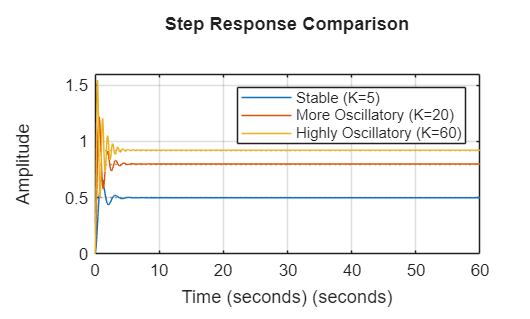

clc;
clear;
close all;

s = tf('s');

% Drone plant
G = 1/(s^2 + 2*s + 5);

% Different proportional gains
K1 = 5;
K2 = 20;
K3 = 60;

% Closed-loop systems with P controller
T1 = feedback(K1*G, 1);
T2 = feedback(K2*G, 1);
T3 = feedback(K3*G, 1);

% Plot step responses
figure;
step(T1, T2, T3, 60);
grid on;

title('Step Response Comparison');
xlabel('Time (seconds)');
ylabel('Amplitude');

legend('Stable (K=5)', ...
       'More Oscillatory (K=20)', ...
       'Highly Oscillatory (K=60)');